# Cardiac 0914 Day21 Run

## Run pipeline

% uint16 images
run_id = 'max';

input_path = 'F:/2020-09-14-Cardiac-Day21/';
input_dim = [1024 1024 66 4 5];

useGPU = true;

data_dirs = dir(fullfile(input_path, "round1", "position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);
% data_dirs = data_dirs(1:1)

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

for p=1:Ndirs

    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
               
    sdata_start = tic;
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    fprintf(sdata.log, sprintf("====Current Position: %s====\n", curr_data_dir));
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', input_dim);
    sdata = sdata.SwapChannels; % !!
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;
    sdata = sdata.xxx_LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
    
    sdata = sdata.LoadCodebook;
    sdata = sdata.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, ...
                             'volumeThreshold', 1, 'barcodeMethod', "iteration", 'showPlots', true);
    sdata = sdata.ReadsExtraction('showPlots', false, 'voxelSize', [1 1 1]); 
    sdata = sdata.ReadsFiltration('showPlots', false);
    
    % Save registered image
    output_dir = fullfile(curr_out_path, 'registered_image');
    if ~exist(output_dir, 'dir')
       mkdir(output_dir);
    end
    new_SaveImg(output_dir, sdata.registeredImages);
    
    % Save points 
    goodReads = sdata.goodReads;
    goodSpots = sdata.goodSpots;
    save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'goodReads', 'goodSpots');
    
    reset(gpuDevice)
    
    fclose(sdata.log);
    upd(p);
    
    fprintf(sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));
    
end

## Plot dots on DAPI

run_id = 'max';
saveAS = true;

input_path = 'F:/2020-09-14-Cardiac-Day21/';

data_dirs = dir(fullfile(input_path, "round1", "position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);
% data_dirs = data_dirs(1:1)

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--

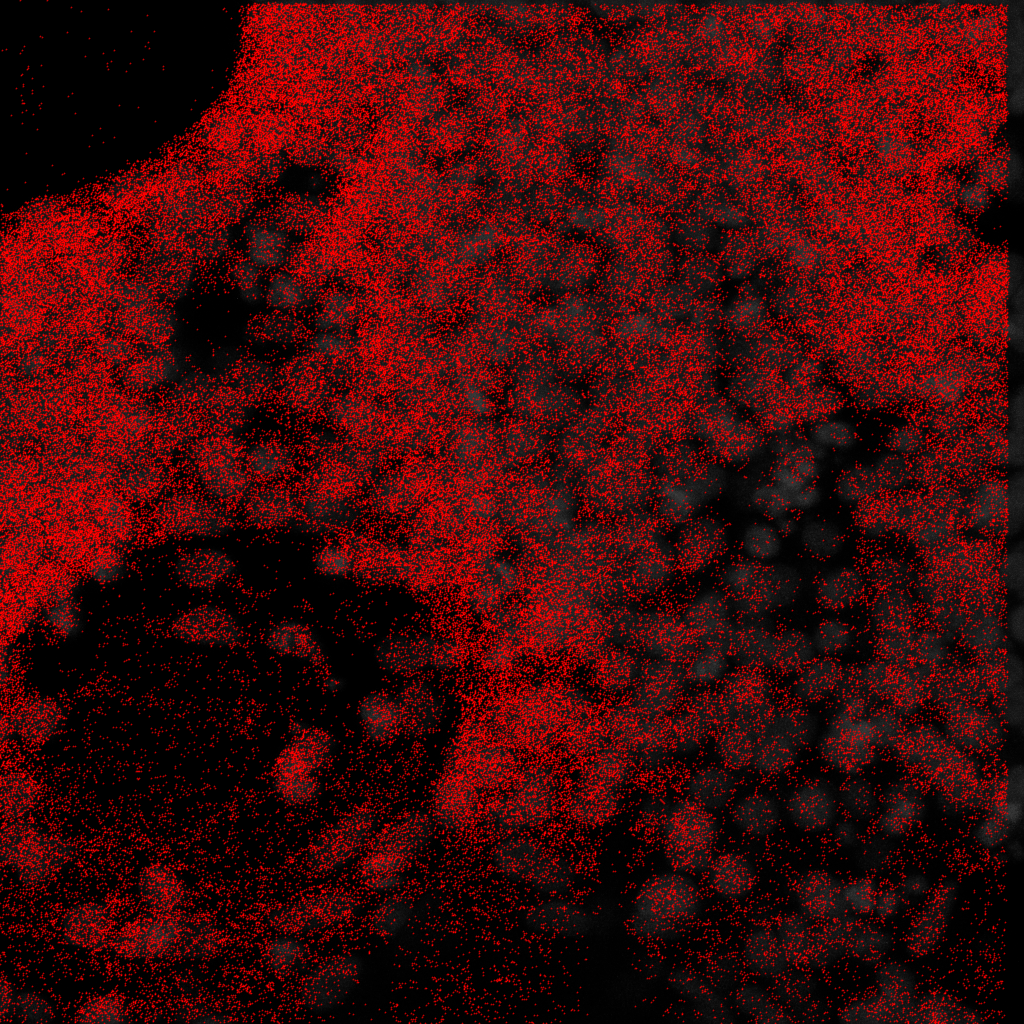

====position1 Finished [time=4.791422]====


for p=1:Ndirs

    sdata_start = tic;
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir);

    curr_dapi_path = dir(fullfile(input_path, "round1", curr_data_dir, "*.tif"));
    curr_dapi_path = fullfile(curr_dapi_path(5).folder, curr_dapi_path(5).name);
    curr_dapi_img = new_LoadMultipageTiff(curr_dapi_path, 'uint16', 'uint8', false);
    curr_dapi_img = max(curr_dapi_img, [], 3);
    
    curr_dot_path = fullfile(curr_out_path, "goodPoints_max3d.mat");
    load(curr_dot_path);
    
    fh = figure('Position', [0 0 1024 1024]);
    ah = axes('Units','Normalize','Position', [0 0 1 1]);
    imshow(curr_dapi_img)
    hold on
    plot(goodSpots(:,1), goodSpots(:,2), '.', "Color", 'red', "MarkerSize", 1)
    hold off
    axis(ah, 'square');
    fh.Position(3) = fh.Position(4);
    
    
    if saveAS
        fig_name = fullfile(curr_out_path, "goodSpots.png");
        saveas(gcf, fig_name)
    end

    
    fprintf(sprintf("====%s Finished [time=%02f]====", curr_data_dir, toc(sdata_start)));
    
end